T = readtable("portfolio list.xlsx")

T = 1008×6 table
       Date         VIPS      BIDU      WNS       JD       GPN  
    ___________    ______    ______    _____    ______    ______

    04-May-2020    14.583     94.76    48.07    39.468    157.97
    05-May-2020    14.788     95.77    48.03    40.281    162.38
    06-May-2020    14.076     97.08    47.84    40.449    165.45
    07-May-2020    14.768     98.18    47.34    41.813    169.98
    08-May-2020    16.758     99.77    48.19      43.7    170.25
    11-May-2020    16.797     99.55    46.06    43.644    167.97
    12-May-2020    16.944     97.47    42.86    43.933    162.74
    13-May-2020    16.885     95.49    39.73    44.662     158.5
    14-May-2020     16.29     96.02    40.68    45.736    159.81
    15-May-2020    16.436     99.86    40.14    47.502    165.2

symbol = T.Properties.VariableNames(2:end)';
dailyReturn = tick2ret(T{:,2:end});
p = Portfolio('AssetList',symbol,'RiskFreeRate',0/252);
p = estimateAssetMoments(p, dailyReturn);
p = setDefaultConstraints(p);
disp = p

disp =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 0
        AssetMean: [5×1 double]
       AssetCovar: [5×5 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 5
        AssetList: {'VIPS'  'BIDU'  'WNS'  'JD'  'GPN'}
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [5×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [5×1 categorical]


w1 = estimateMaxSharpeRatio(p)

w1 =     0.4358
    0.4630
    0.1013
    0.0000
    0.0000


[risk1, ret1] = estimatePortMoments(p, w1)

risk1 = 0.0297

ret1 = 7.3632e-04

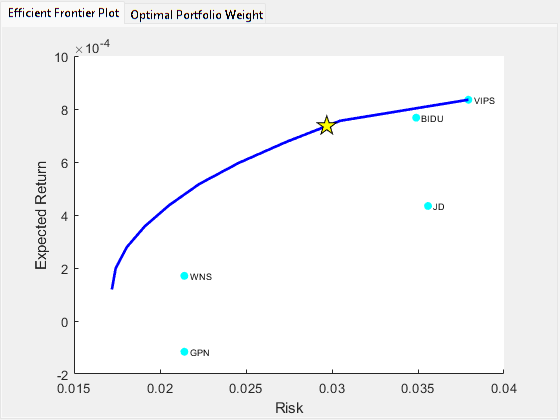

f = figure;
tabgp = uitabgroup(f); % Define tab group
tab1 = uitab(tabgp,'Title','Efficient Frontier Plot'); % Create tab
ax = axes('Parent', tab1);
% Extract asset moments from portfolio and store in m and cov
[m, cov] = getAssetMoments(p); 
scatter(ax,sqrt(diag(cov)), m,'oc','filled'); % Plot mean and s.d.
xlabel('Risk')
ylabel('Expected Return')
text(sqrt(diag(cov))+0.0003,m,symbol,'FontSize',7); % Label ticker names
hold on;
[risk2, ret2]  = plotFrontier(p,10);
plot(risk1,ret1,'p','markers',15,'MarkerEdgeColor','k',...
                'MarkerFaceColor','y');
hold off

tab2 = uitab(tabgp,'Title','Optimal Portfolio Weight'); % Create tab
% Column names and column format
columnname = {'Ticker','Weight (%)'};
columnformat = {'char','numeric'};
% Define the data as a cell array
data = table2cell(table(symbol(w1>0),w1(w1>0)*100));
% Create the uitable
uit = uitable(tab2, 'Data', data,... 
            'ColumnName', columnname,...
            'ColumnFormat', columnformat,...
            'RowName',[]);
% Set width and height
uit.Position(3) = 450; % Widght
uit.Position(4) = 350; % Height

%estimatefrontierbyreturns
%estimatefrontierbyrisk
